# IMPORTANT: BEFORE YOU START!

Do **NOT** click on the green run button!

Execute this script by stepping section to section, read instructions and inspect results.

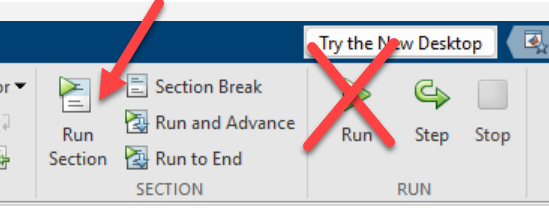

Before you start with the exercises, let's add the folder with the files and solutions required to complete each step.

close all;
clear all;
bdclose all;
clc;

addpath('./Solutions')
addpath('./Files')

## Exercise 3: Integrate a dipole antenna 

Number of steps: 5

Expected completion time: 20 minutes

In this exercise, you integrate a simple dipole antenna in the RF receiver and experiment with changing the polarization of the incoming signals.

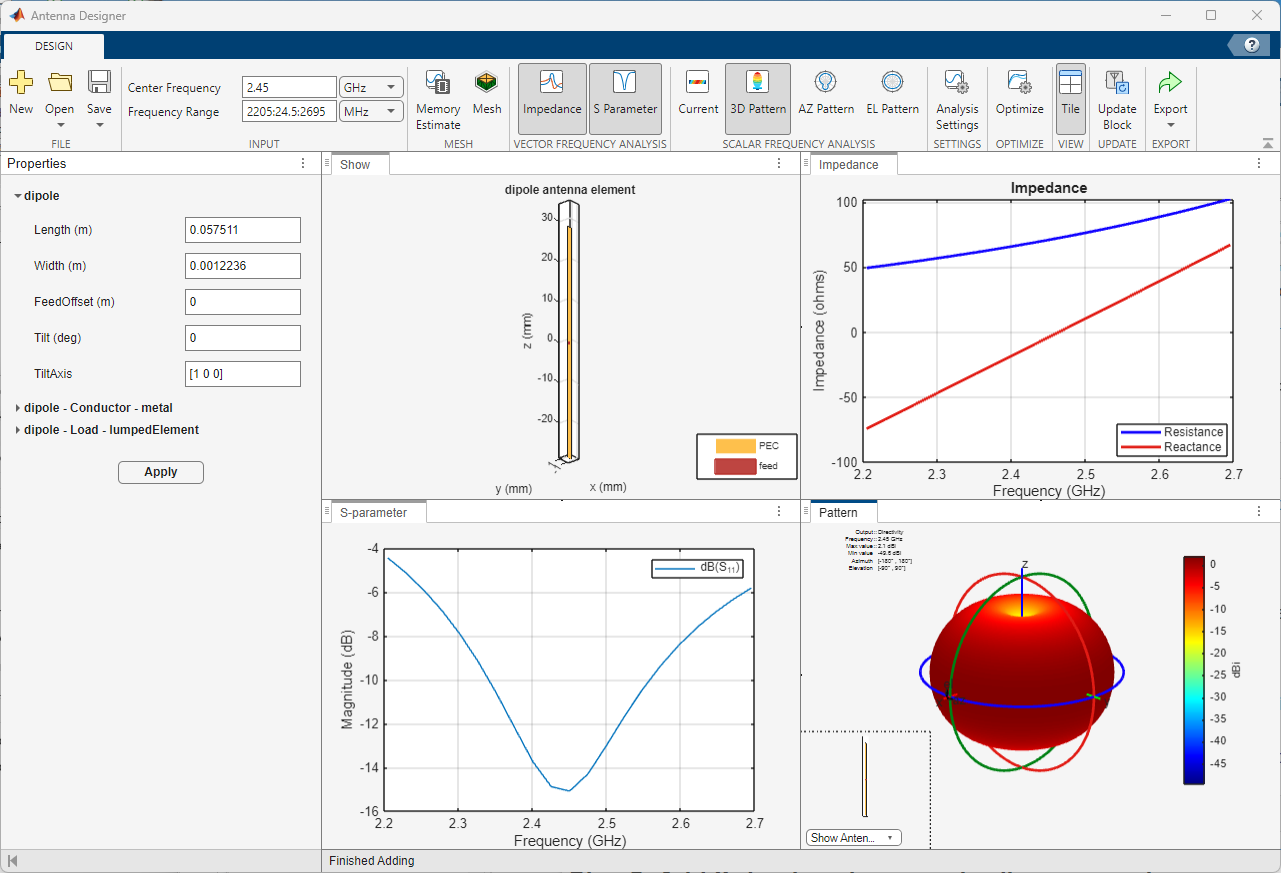

**3.1 **Open the Simulink testbench `Exercise2_RFReceiverWithAntenna`, and **open the RF receiver subsystem**. Notice that the input port is missing.

open_system('Exercise2_RFReceiverWithAntenna.slx')

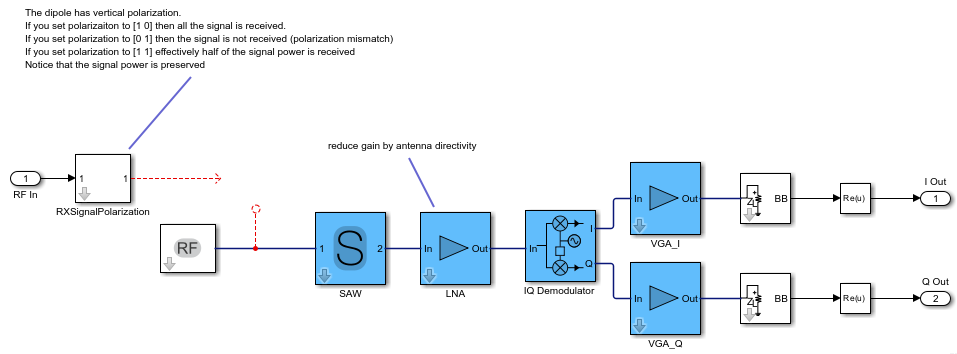

**3.2** Insert an **antenna block from the RF Blockset Circuit Envelope library**. You can either open the Simulink library browser, or simply type "antenna" in the Simulink canvas. 

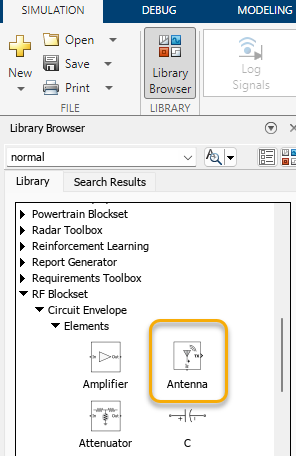

**3.3** Open the mask of the antenna block (double click) and configure it as following: 

- the antenna should operate in receiving mode

- change the  units to Hz in the carrier frequency field:

- the incident carrier frequencies should be set by the variable `carrierFreqs` defined in the workspace 

- set the source of the antenna model to be `Antenna Designer`

The mask of the antenna block shouls look as following before clicking on the button `Create Antenna` to open the Antenna Designer app

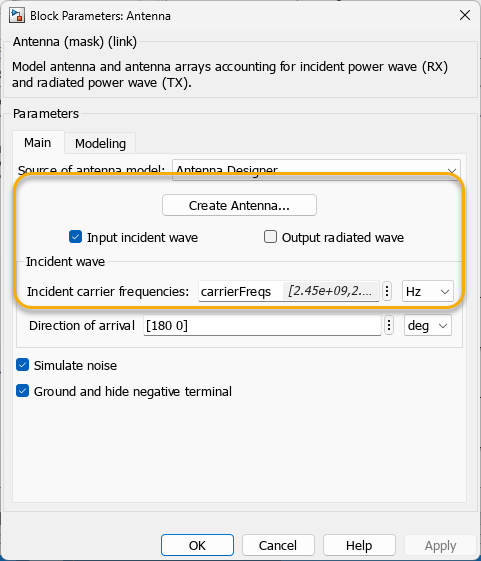

**3.4** In the Antenna designer app, **design** a dipole antenna at the operating input frequency:

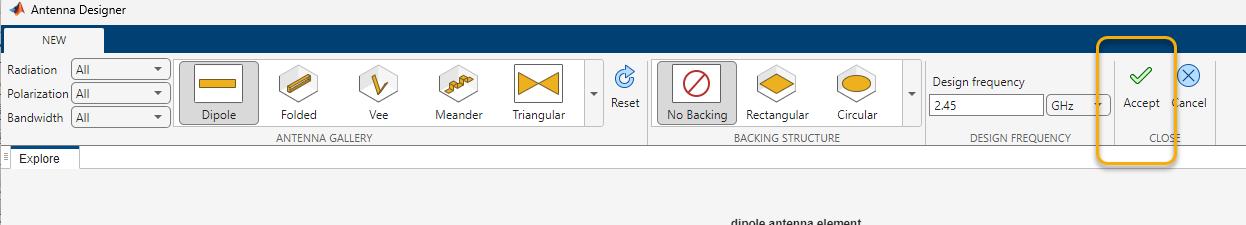

Analyze the antenna **S-parameters **and** far-field radiation pattern** as shown in the image at the beginning of the second exercise. 

Click on `Update Block` and return to the Simulink testbench.

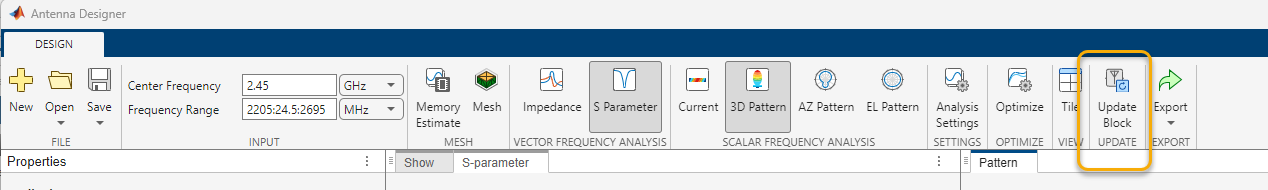

The antenna block is now fully configured.

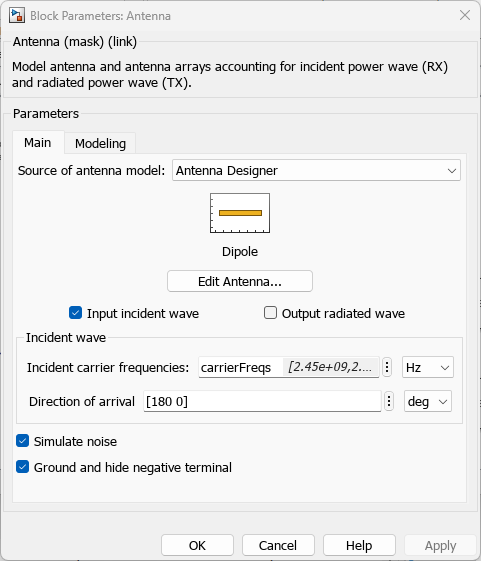

Connect the antenna block to the RF Receiver and run the simulation. 

The ChER should be around 5%.

**3.5** Open the mask parameters of the subsystem `RXSignalPolarization`, and verify the spectrum of the output signal and ChER in the following scenarios:

- Polarization Interferer = [1 0], without DC offset removal (results in the left image below)

- Polarization Interferer = [0 1], without DC offset removal (results in the right image below)

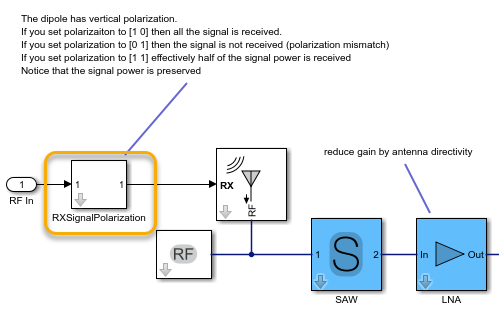

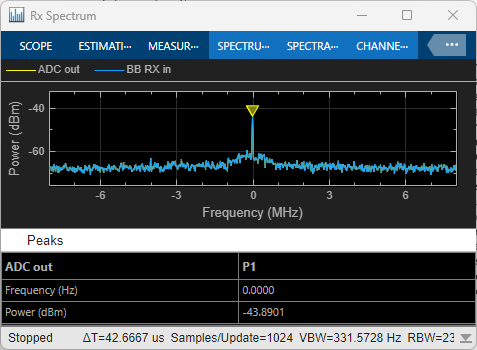 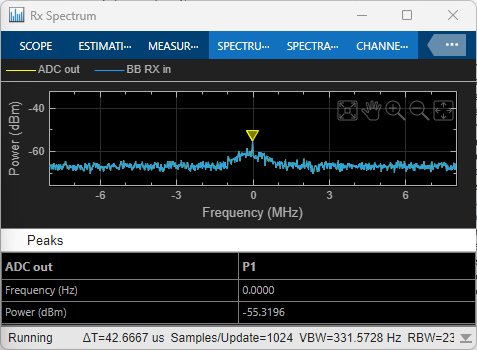

*Why is the ChER still acceptable even without DC offset correction, when the polarization of the interfering signal lies entirely on the horizontal plane?*

**Solution **

Open the resulting integrated model:

open_system('Solution2_RFReceiverWithAntenna.slx')

The dipole is a linearly polarized antenna along the vertical plane, hence incoming signals with horizontal polarization are not received.

Extra: you can verify the updated budget including the antenna block. Notice that to maintain the output power consistent with the initial budget, the amplifier gain was reduced by 2dB, the same amount as the antenna directivity gain.

rfBudgetAnalyzer('rfbudget_RFReceiverAntenna.mat') 

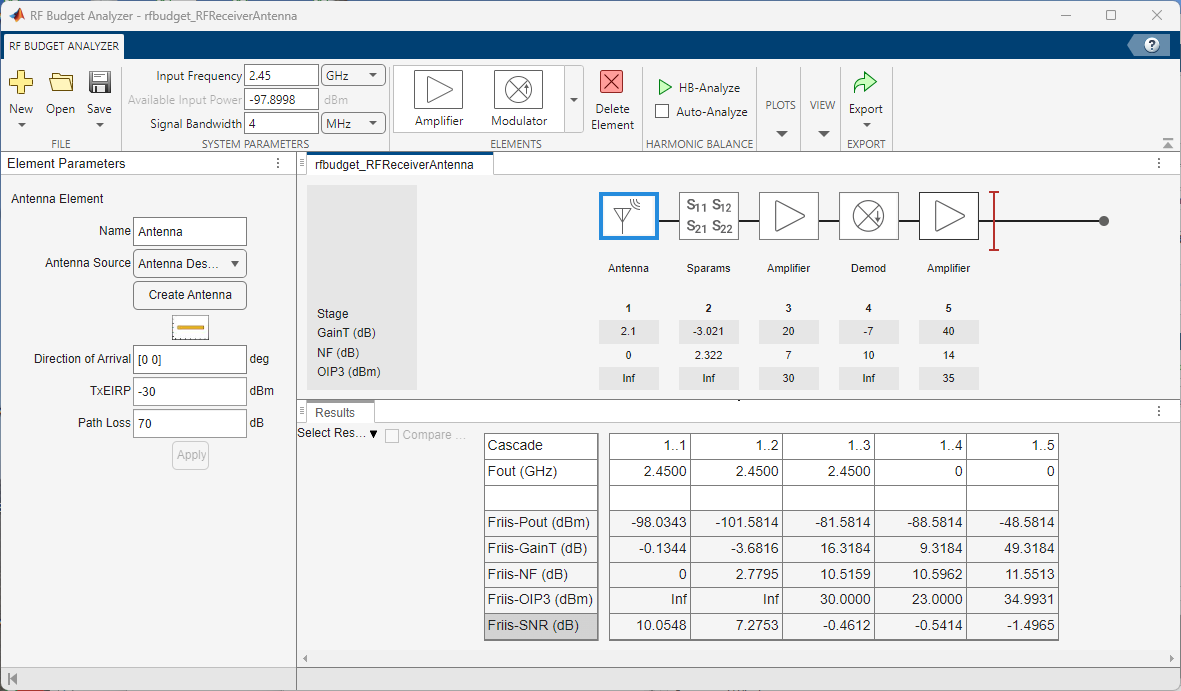

**Exercise outcome and summary**

In this exercise, you learned how to design an antenna in MATLAB using electromagnetic analysis and integrate its characteristics in the budget analysis as well as the simulation model. You experimented with polarization mismatch, and direction of arrival.